# **Servo Motor Control Design Activity Sheet**

**Student Name**: Alex Ong

**Student Number: n12435562**

### **Preparations for the task:**

The next code helps prepare your MATLAB work space (you don't need to edit, unless error occurs)

%The next 3 lines change MATLAB's current working folder to this .mlx script's current location.
filePath = matlab.desktop.editor.getActiveFilename;
filePath = fileparts(filePath);
cd(filePath)
%If causes a MATLAB error on your computer, remove these 3 code lines and manually change folder.

clear all
close all

# Overview

In this activity you will work with the **input to shaft angle position** servo motor transfer function:

                              
$$G(s)=\frac{\Theta(s)}{V_m(s)}=\frac{K_m}{s(s+\alpha)}$$
         

and investigate (unity) negative feedback for shaft angle position control based on shaft angle measurements. Here $V_m$ is input signal and $\Theta$ is output shaft position. 

# Assessed Tasks – Coz`ntrol System Design

*In the following, you will perform a control system design for the “***input to shaft angle position** **servo motor”** ***with the parameter values you examined in the EGB345 Servo Motor System Identification task.***

**Preliminary information:** your servo motor parameter values for this activity.

In the below tasks use for your servo motor parameter values,  and *a**, *the following: 

- The $K_m$ and $\alpha$ values provided in Task 1.1 of the EGB345 Servo Motor System Identification task. 

In this activity we investigate (unity) negative feedback closed-loop system, where the “unity” means consider H=1 on the feedback path.  

## Task 1: Design feedback control for a requested response

Aim: Build a MATLAB representation of your servo motor system, design feedback control and simulate.

In the MATLAB for this task use the following MATLAB variables in your MATLAB:

*km, alpha, KTask1.*

Complete the following sub-tasks:

#### Task 1.1: 

Build a MATLAB representation of the **input to shaft angle position **servo motor in open loop (i.e. no controller and no feedback) having your servo motor parameter values. We call this representation *your open-loop system*. Analytically assess the expected unit step response of your open loop system. Plot the unit step response of your open-loop system. Comment on whether the plot matches your analytic assessment.

***ANSWER (edit below code block)***

%edit here
km = 9.76

km = 9.7600

alpha = 4.59

alpha = 4.5900

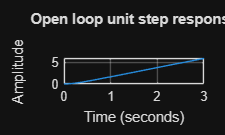

s = tf('s');
G = km/(s*(s+alpha));
figure; step(G, 3); grid on
title('Open loop unit step response')

***ANSWER (edit below text section)***

<Edit Here>

#### Task 1.2: 

Analytically create the transfer function expression of a (unity) negative feedback closed-loop system containing a general gain K controller in front of your open-loop system. 

***ANSWER (edit below text section)***

<Edit Here>

#### Task 1.3: 

For *K=1*, if underdamped in closed-loop, analytically determine the settling time and % overshoot. Note we don’t have an analytic formula for over-damped systems, and the formula is not accurate if the system is only slightly underdamped. Hence, if overdamped, or if only slightly underdamped, in closed-loop then use a MATLAB generated unit step response plot to graphically estimate settling time (after completing Task 1.5 below).

***ANSWER (if needed, edit below code block)***

% Only need if your system is overdamped, or close to overdamped.

***ANSWER (edit below text section)***

<Edit Here>

#### Task 1.4: 

Using mathematical analysis, determine a value of *K *that results in a 5% overshoot. Report the location of the closed-loop poles that would result. Label this designed gain *KTask1 *(i.e. K from task 1).

***ANSWER (edit below text section)***

KTask1 = 1.135

#### Task 1.5: 

Build an appropriate MATLAB representation of the closed-loop system for *K=1*. Plot the unit step response of the closed-loop system.

 Your MATLAB code:

%edit here
K1 = 1;
T1 = feedback(K1*G,1);
zeta = -log(0.05)/sqrt(pi^2+log(0.05)^2);
KTask1 = (alpha/(2*zeta))^2/km;
T6 = feedback(KTask1*G,1);

#### Task 1.6: 

Build an appropriate MATLAB representation of the closed-loop system with the designed value of *K *for 5% overshoot (i.e. *KTask1)*.  Plot the unit step response of the closed-loop system.

 Your MATLAB code:

%edit here
KTask1 = 1.135

KTask1 = 1.1350

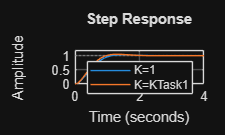

figure; step(T1,T6,4); grid on; legend('K=1','K=KTask1')

stepinfo(T1), stepinfo(T6), pole(T6)

ans = struct with fields:
         RiseTime: 0.7159
    TransientTime: 1.8736
     SettlingTime: 1.8736
      SettlingMin: 0.9027
      SettlingMax: 1.0333
        Overshoot: 3.3323
       Undershoot: 0
             Peak: 1.0333
         PeakTime: 1.4849


ans = struct with fields:
         RiseTime: 0.6306
    TransientTime: 1.8028
     SettlingTime: 1.8028
      SettlingMin: 0.9005
      SettlingMax: 1.0500
        Overshoot: 5.0000
       Undershoot: 0
             Peak: 1.0500
         PeakTime: 1.3043


ans =   -2.2950 + 2.4067i
  -2.2950 - 2.4067i


#### Task 1.7: 

Comment on whether the 3 unit step responses seen in the previous tasks (Task 1.1, 1.5 and 1.6) match your analytic results (quantitative and qualitative assessment).

***ANSWER (edit below text section)***

Quantitative

- Overshoot is similar in both cases.

- Simulation settling time is slightly longer due to the 2nd-order approximation.

- Both final values are 1, as predicted by T(0)=1.

Qualitative

- Feedback makes the ramp response stable.

- Increasing K from 1 to 1.145 raises overshoot from 3% to 5% as daping ratio drops from 0.74 to 0.69.

- Both systems have poles with real part -2.3, so settling times are similar.

- The plant's integrator gives zero steady-state error to a step.

Here and below, the word “analytically” means the outcome of mathematical analysis, see Learning Requirements and Expectations module on CANVAS for more explanation. We would expect several mathematical operations deriving the required mathematical object.

## Task 2:Investigation of the gain K  

Aim: Evaluate the impact of errors in the value of designed K (i.e. *KTask1*), such as arises due to imperfect hardware components. 

Complete the following sub-tasks:

#### Task 2.1: 

Analytically determine the location of the (unity) negative feedback closed-loop poles for at least 5 values of *K* below and at least 5 values above the K value you designed in Task 1 (i.e. *KTask1*). Ensure a selection of *K* values so that the closed-loop system shows examples of both over and underdamped closed-loop unit step response behaviour.  

We initially suggest increasing and decreasing by a factor of 20% (that is 0.8**KTask1*, 0.6** KTask1*, …    and 1.2** KTask1* etc., but avoid using 0** KTask1*). Ensure you select a range of *K* values showing examples for both over and underdamped closed-loop unit step response behaviour in closed-loop. 

Identify one underdamped pole. Identify one overdamped pole. Explain the meaning and significance of your choices. 

***ANSWER (edit below text section)***

<Edit Here> 

#### Task 2.2: 

Neatly hand draw a graph in the s-plane that reports the closed-loop pole locations used in the previous sub-task (on paper or electronic equivalent but MATLAB-generated plots are not accepted for this specific sub-task). Neatly label a couple of the poles with their corresponding* K* value. Comment on the meaning of what you see in the graph you have drawn (quantitative and qualitative assessment). Provide connections to concepts encountered in lectures (qualitative).

***ANSWER (edit below text section)***

<Edit Here> 

#### Task 2.3: 

Using your MATLAB representation of the closed-loop system, plot the unit step response of the following 3 cases: the designed *K (i.e. KTask1)*, and the largest and smallest values of *K* you tested in the above sub-tasks. Comment on what you see in the unit step response plots (quantitative and qualitative assessment).

***ANSWER (edit below code block)***

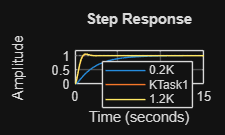

%edit here
Ks = [0.2 1.135 1.2];
figure; hold on
for k = Ks, step(feedback(k*G,1),15); end
legend('0.2K','KTask1','1.2K'); grid on

***ANSWER (edit below text section)***

Quantitative

- Lowest K has no overshoot but takes 4 times longer to settle.

- Designed K gives 5% overshoot.

- Doubling K gives 17% overshoot, with similar settling time (1.73 s vs 1.80 s).

Qualitative

- Low K: smooth but slow.

- High K: faster rise and more oscillation.

- All settle at 1 due to the plant's integrator.

- A ±20% error in K changes overshoot from 5% to about 2% or 8%.

## Task 3: Robustness study - an extra unmodelled fast pole  

Aim: Investigate the impact of an extra unmodelled fast pole. 

You are told the true system has an additional fast pole at $\beta$ and is described by: 

                 
$$G_{extra}(s)=\frac{\Theta(s)}{V_m(s)}=\frac{\beta K_m}{s(s+\alpha)(s+\beta)}$$


You are told the unmodelled pole at -$\beta$  is faster than the pole at -$\alpha$  but you don’t know how much faster (“unmodelled” means you didn’t know the pole was present and/or didn’t know its specific value). Note the extra   factor in the numerator ensures the systems with different extra poles have the same final value for their unit step response (in open-loop).

You do not need to consider the gain error issue considered in Task 2.

Consider the three systems:

- No extra pole (same as used in Task 1 and elsewhere):


$$G_{ne}(s)=\frac{\Theta(s)}{V_m(s)}=\frac{K_m}{s(s+\alpha)}$$


- Fast extra pole where $\beta=10\alpha$


$$G_{fo}(s)=\frac{\Theta(s)}{V_m(s)}=\frac{10\alpha K_m}{s(s+\alpha)(s+10\alpha)}$$


- Slow extra pole where $\beta=2\alpha$


$$G_{so}(s)=\frac{\Theta(s)}{V_m(s)}=\frac{2\alpha K_m}{s(s+\alpha)(s+2\alpha)}$$


In Task 1 you previously designed a gain *K *for (unity) negative feedback closed loop system to achieve a 5% overshoot assuming no extra pole system. Reused this previously designed gain *KTask1 *(i.e. K designed from sub-task 1.6). 

In the MATLAB for this task use the following MATLAB variables in your MATLAB:

*km, alpha, KTask1, Kfo, Kso, *

In this task you must use the root locus graphical design method taught in the last few lectures of EGB345.

Complete the following sub-tasks:

#### Task 3.1: 

Complete the hand graphical and analytic steps to design a new controller gain *K* (for (unity) negative feedback closed loop system) to achieve 5% overshoot assuming that $G_{fo}(s)$ is the true model. You should hand draw the root locus. Label this designed gain *Kfo*. 

***ANSWER (edit below text section)***

<Edit Here> 

Now check your design for 5% overshoot by plotting the unit step response (qualitative assessment). Provide this unit step response.

***ANSWER (edit below code block)***

%edit here
Kfo = 1.035;
Kso = 0.744;
figure; step(feedback(Kfo*Gf,1),3); title('Kfo on Gf'); grid on

Unrecognized function or variable 'Gf'.

figure; step(feedback(Kso*Gs,1),4); title('Kso on Gs'); grid on
stepinfo(feedback(Kfo*Gf,1)), stepinfo(feedback(Kso*Gs,1))

#### Task 3.2: 

Complete the hand graphical and analytic steps to design a new controller gain *K* (for (unity) negative feedback closed loop system) to achieve 5% overshoot assuming that $G_{so}(s)$ is the true model. You should hand draw the root locus. Label this designed gain *Kso*. 

***ANSWER (edit below text section)***

<Edit Here> 

Now check your design for 5% overshoot by plotting the unit step response (qualitative assessment). Provide this unit step response.

***ANSWER (edit below code block)***

%edit here
Kall = [KTask1 Kfo Kso]; Kname = {'KTask1','Kfo','Kso'};
Gall = {G, Gf, Gs};      Gname = {'G','Gf','Gs'};
n = 0; figure
for i = 1:3
  for j = 1:3
    if i~=j
      n = n+1; subplot(2,3,n)
      step(feedback(Kall(i)*Gall{j},1),6); grid on
      title([Kname{i} ' on ' Gname{j}])
    end
  end
end

#### Task 3.3: 

Now consider the three gain designs (*KTask1*, *Kfo* and *Kso*) and the three systems ($G_{ne}(s)$,$G_{fo}(s)$ or $G_{so}(s)$) and investigate each of gains when they are used in a situation *other than they were initially designed* (this type of situation is called design mismatch). There are three gain designs each with 2 possible mismatched systems (the other two systems) which means there are 6 mismatch cases to consider. For example, *KTask1 *can be considered in (unity) negative feedback closed loop with both $G_{fo}(s)$ and $G_{so}(s)$ . You are asked to provide plots of the unit step responses for each of the 6 cases where control gains are applied to a system for which not designed and provide a qualitative assessment.  There are 6 plots.

***ANSWER (edit below code block)***

%edit here 
%% Task 3.3 : the six design-mismatch cases -------------------------------
Kall  = [KTask1  Kfo    Kso   ];   Kname = {'K_{Task1}', 'K_{fo}', 'K_{so}'};
Gall  = {Gne,    Gfo,   Gso   };   Gname = {'G_{ne}', 'G_{fo}', 'G_{so}'};
 
figure; n = 0;
for i = 1:3                         % which gain
    for j = 1:3                     % which system
        if i ~= j                   % skip the three matched (designed) cases
            n = n + 1;
            subplot(2,3,n);
            Tm = feedback(Kall(i)*Gall{j}, 1);
            step(Tm, 6); grid on; yline(1.05, 'r--');
            info = stepinfo(Tm);
            title(sprintf('%s on %s: OS %.1f%%, Ts %.2f s', ...
                  Kname{i}, Gname{j}, info.Overshoot, info.SettlingTime));
        end
    end
end
sgtitle('Task 3.3: design mismatch cases (red dashed = 5% overshoot limit)');
saveas(gcf, 'task3_3_mismatch.png');

#### Task 3.4: 

Compare and contrast the performance of the controllers, and report what design considerations are important (quantitative and qualitative assessment).  For example, would your *KTask1 *designed gain work on $G_{fo}(s)$? Can you explain in terms of any concepts encountered in lectures, tutorials or practicals? If so, provide this explanation.  

***ANSWER (edit below text section)***

Quantitative

- KTask1 gives 4.9% overshoot on the model, but 6.5% and 15.6% with an extra pole.

- The slow-pole system has the highest overshoot (15.6%, 12.9%, 4.8%).

- Kso keeps overshoot at or below 5%, but takes longer to settle on Gso (2.47 s).

Qualitative

- Dominant pole: The 2nd-order approximation works better when extra poles are far away. Pole 46 is fast, while 9.2 affects the response more.

- Root locus: Extra poles reduce stability, lowering the limit from K = 24 to K = 6.5.

- Design mismatch: Ignoring poles can cause more overshoot, especially at higher gain.

- Trade-off: Lower gain is safer but slower.

#### Task 3.5: 

You are told that the implemented closed-loop system should have %5 overshoot or less. You are told you don’t which system is present (that is, might be $G_{ne}(s)$,$G_{fo}(s)$ or $G_{so}(s)$). You are told you must select one of the designed gains (*KTask1*, *Kfo* or *Kso*) to be your robust gain. Which gain would you recommend as suitable to be your robust gain?

***ANSWER (edit below text section)***

<Edit Here> 

 Now check your choice achieves the requirement for each of $G_{ne}(s)$,$G_{fo}(s)$ and$G_{so}(s)$

 Your MATLAB code:

%edit here 
OS = zeros(3,3);                    % rows = gain, columns = system
TS = zeros(3,3);
for i = 1:3
    for j = 1:3
        info    = stepinfo(feedback(Kall(i)*Gall{j}, 1));
        OS(i,j) = info.Overshoot;
        TS(i,j) = info.SettlingTime;
    end
end
 
fprintf('\nOvershoot (%%): rows = KTask1, Kfo, Kso; columns = Gne, Gfo, Gso\n');
disp(round(OS, 2));
fprintf('Settling time (s):\n');
disp(round(TS, 2));
 
ok = all(OS <= 5, 2);               % must be <= 5%% on ALL three systems
fprintf('Gain meets the 5%% limit on all systems?\n');
for i = 1:3
    fprintf('  %-9s : %d   (worst-case OS = %.2f%%)\n', ...
            erase(Kname{i}, {'{','}','_'}), ok(i), max(OS(i,:)));
end
 
Krobust = Kall(find(ok, 1));        % first gain that passes (expected: Kso)
fprintf('Recommended robust gain = %.3f\n', Krobust);
 
figure; hold on
for j = 1:3
    step(feedback(Krobust*Gall{j}, 1), 6);
end
yline(1.05, 'r--', '5% limit'); grid on;
legend(Gname, 'Location', 'southeast');
title(sprintf('Task 3.5: robust gain K = %.3f on all three systems', Krobust));
saveas(gcf, 'task3_5_robust.png');

## Task 4: Improved transient response using a dynamic compensator  

You now introduce dynamic compensation via lead compensation designed so that the closed-loop system has *half the settling time *achieved in Task 1 (i.e. with designed K, *KTask1*), has the same overshoot, and keeps the same steady-state error to unit step input. (Here, “dynamic compensation” is the same as a “dynamic controller” and means a controller with poles and/or zeros). 

You do not need to consider the gain issue considering in Task 2. Further, you do not need to consider the extra pole examined in Task 3. That is, your work on this task may be based on the Task 1 open loop system $G(s)$.                              . 

In this task, you are to use a root locus control design approach for a (unity) negative feedback closed loop system. You may use other compensators, but one useful compensator is a lead compensator which has the transfer function with one zero $z_c$ and one pole $p_c$(with $z_c < p_c$)

                              
$$\frac{s+z_c}{s+p_c}$$


In the MATLAB for this task use the following MATLAB variables in your MATLAB:

*km, alpha, Pc, Zc, Klead.*

In this task you must use the root locus hand-graphical design method taught in the last few lectures of EGB345. You should hand draw the root locus.

Complete the following sub-tasks:

#### Task 4.1: 

Determine the location of the desired closed-loop poles for the designed closed-loop system to achieve the requested response.

***ANSWER (edit below text section)***

<Edit Here> 

#### Task 4.2: 

Using hand graphical and analytic considerations, determine the location of your compensator’s pole and zero location that allows you to achieve the requested unit step response. Label these designed locations *Pc *and* Zc*, respectively.

***ANSWER (edit below text section)***

<Edit Here> 

#### Task 4.3: 

Determine the value of *K *that achieves the requested unit step response (with the above step 2 poles and zeros) of the designed closed loop system. Label this designed gain *Klead*.

***ANSWER (edit below text section)***

<Edit Here> 

#### Task 4.4: 

Using your MATLAB representation of the closed-loop system, make modifications to include the designed compensator (designed in the above sub-task 4.2 & 4.3), and provide a plot of its unit step response. Comment on the meaning of what you see (quantitative and qualitative). What are the closed-loop pole (and zero) locations (quantitative)? What is the settling time and %OS of your design (quantitative)? 

***ANSWER (edit below code block)***

%edit here
Zc = 4.6; 
Pc = 9.2; 
Klead = 4.51;
C = Klead*(s+Zc)/(s+Pc);
Tl = feedback(C*G,1);
figure; step(Tl,3); grid on
stepinfo(Tl), pole(Tl), zero(Tl)

***ANSWER (edit below text section)***

Quantitative

- Settling time halves (0.90 s vs 1.81 s), with overshoot unchanged at 4.87%.

- Rise time and peak time also halve.

Qualitative

- The poles move further from the origin, doubling speed while keeping the same damping.

- Step error stays zero because the plant's integrator remains.

- Kv roughly doubles (4.79 vs 2.39), halving ramp error.

- If alpha is not exact, pole-zero cancellation leaves a slow pair near −4.6.

- Lead compensation moves the locus left, improving speed and stability.

# Do not change below: Check for "Ready to Submit". 

This script checks your code's variable names. Will confirm if ready to submit. Creates a design summary that is used to evaluate your activity.

EGB345_DataNameChecker_Control